## Steel Plate Defects

**Background:** [**Steel plate defects**](https://apmonitor.com/pds/uploads/Main/steel.txt) are extracted from photos of several faulty steel plates with surface imperfections. Image analysis revealed 27 different features to describe the steel fault. A total of 6 unique types of faults are categorized, with a final category of "other faults" for any type of fault that does not fit into the other specific 6 categories.

url = 'http://apmonitor.com/pds/uploads/Main/steel.txt';
data = readtable(url);
head(data);

    X_Minimum    X_Maximum    Y_Minimum     Y_Maximum     Pixels_Areas    X_Perimeter    Y_Perimeter    Sum_of_Luminosity    Minimum_of_Luminosity    Maximum_of_Luminosity    Length_of_Conveyer    TypeOfSteel_A300    TypeOfSteel_A400    Steel_Plate_Thickness    Edges_Index    Empty_Index    Square_Index    Outside_X_Index    Edges_X_Index    Edges_Y_Index    Outside_Global_Index    LogOfAreas    Log_X_Index    Log_Y_Index    Orientation_Index    Luminosity_Index    SigmoidOfAreas    Pastry    Z_Scratch

**Features:** There are 27 features that are used to predict the steel faults. These features are extracted from steel plate samples. Computer vision can automatically extract some of this information from images or manually extracted with a user inspecting each plate defect or photo of the steel plate.

- X_Minimum

- X_Maximum

- Y_Minimum

- Y_Maximum

- Pixels_Areas

- X_Perimeter

- Y_Perimeter

- Sum_of_Luminosity

- Minimum_of_Luminosity

- Maximum_of_Luminosity

- Length_of_Conveyer

- TypeOfSteel_A300

- TypeOfSteel_A400

- Steel_Plate_Thickness

- Edges_Index

- Empty_Index

- Square_Index

- Outside_X_Index

- Edges_X_Index

- Edges_Y_Index

- Outside_Global_Index

- LogOfAreas

- Log_X_Index

- Log_Y_Index

- Orientation_Index

- Luminosity_Index

- SigmoidOfAreas

**Labels:** There are 7 types of steel plate defects that are labelled with a 1 if present and 0 if not present with [**One-Hot Encoding**](https://apmonitor.com/pds/index.php/Main/FeatureEngineering). A unique aspect of this data set is that the labels are imbalanced, meaning that there is a large difference in the number of specific defects.

- Pastry

- Z_Scratch

- K_Scatch

- Stains

- Dirtiness

- Bumps

- Other_Faults

In cases where there is a large imbalance, a strategy is to [**synthetically generate new data sets to improve the balance**](https://machinelearningmastery.com/multi-class-imbalanced-classification/). That strategy is not taken in this case study but could be an option to improve the classification training. The fault label is not stored as a sequential value (e.g. fault label as 0-6) but is [**One-hot encoded**](https://en.wikipedia.org/wiki/One-hot) to translate the fault label into a binary representation (0 or 1) for each fault. There are 7 additional columns of data with 1 if the fault exists and 0 if the fault does not exist.

**Data Exploration:** Generate summary statistics with a profiling report to [**statistically characterize the data**](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify any outliers in the data. Remove any outliers from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to the steel faults? Generate a bar chart that shows the imbalance of faults in the data.

features = data(:,1:27).Properties.VariableNames;
labels = data(:,28:end).Properties.VariableNames

labels = 1×7 cell array
    {'Pastry'}    {'Z_Scratch'}    {'K_Scatch'}    {'Stains'}    {'Dirtiness'}    {'Bumps'}    {'Other_Faults'}


X = data(:,1:27);
y = data(:,28:end);

% counts = groupsummary(y,"Pastry")
% counts = groupcounts(table2array(y))
counts = varfun(@groupcounts,y,"InputVariables",labels);
counts = counts(2,:)

counts = 1×7 table
    groupcounts_Pastry    groupcounts_Z_Scratch    groupcounts_K_Scatch    groupcounts_Stains    groupcounts_Dirtiness    groupcounts_Bumps    groupcounts_Other_Faults
    __________________    _____________________    ____________________    __________________    _____________________    _________________    ________________________

           158                     190                     391                     72                     55                     402                     673           


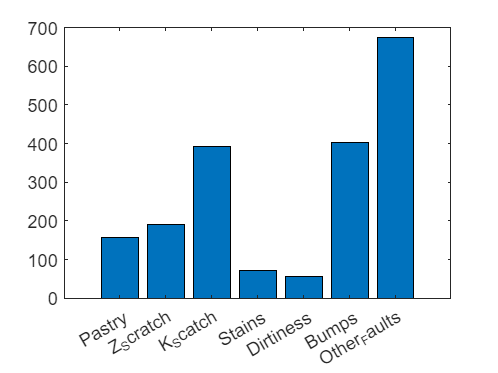

bar(table2array(counts))
set(gca,'XTick',1:length(labels),'XTickLabel',labels)

**Classification of Faults:** Train and test a classifier to distinguish between steel plate faults with Keras / TensorFlow.

Randomly select values that split the data into a train (80%) and test (20%) set by using the *scikit-learn* function *train_test_split*

features = data(:,1:27).Properties.VariableNames;
labels = data(:,28:end).Properties.VariableNames

labels = 1×7 cell array
    {'Pastry'}    {'Z_Scratch'}    {'K_Scatch'}    {'Stains'}    {'Dirtiness'}    {'Bumps'}    {'Other_Faults'}


data_s = fit_tranform(table2array(data))

data_s =     0.0246    0.0269    0.0204    0.0204    0.0017    0.0014    0.0024    0.0021    0.3744    0.3287    0.8113    1.0000         0    0.1538    0.0500    0.2559    0.1750    0.0037    0.4629    1.0000    1.0000    0.4353    0.2171    0.3859    0.9125    0.4312    0.5258    1.0000         0         0         0         0         0         0
    0.3783    0.3786    0.1950    0.1950    0.0007    0.0008    0.0016    0.0010    0.4138    0.3981    0.8113    1.0000         0    0.1538    0.7684    0.4018    0.2003    0.0024    0.5942    0.9650    1.0000    0.3548    0.1721    0.3434    0.8998    0.5017    0.2036    1.0000         0         0         0         0         0         0
    0.4862    0.4862    0.1192    0.1192    0.0005    0.0006    0.0010    0.0007    0.4877    0.4074    0.6984    1.0000         0    0.2308    0.9757    0.3630    0.3277    0.0025    0.7463    0.9447    1.0000    0.3175    0.1721    0.2948    0.8361    0.5339    0.1090    1.0000         0         0         

X = data_s(:,1:27);
y = data_s(:,28:end);


%Split into training and testing data
test_size = 0.2;
idx = randsample(height(X), round(height(y) * test_size));
X_test = X(idx, :);
y_test = y(idx, :);
X_train = X;
X_train(idx, :) = [];
y_train = y;
y_train(idx, :) = [];

Determine any evidence of overfitting by plotting the training and test (validation) loss functions by epoch.

% Define the neural network model
layers = [
%     fullyConnectedLayer(8)

    featureInputLayer(width(X_train))
    reluLayer
    
%     fullyConnectedLayer(size(y_train, 2))
    softmaxLayer
    classificationLayer
];
options = trainingOptions('adam', ...
    'MaxEpochs', 1000, ...
    'ValidationData', {X_test, y_test}, ...
    'ValidationFrequency', 50, ...
    'Plots', 'training-progress');
net = trainNetwork(X_train', categorical(y_train)', layers, options);

Error using trainNetwork
Invalid training data. For classification tasks, responses must be a vector of categorical responses. For regression tasks, responses must
be a vector, a matrix, or a 4-D array of numeric responses which must not contain NaNs.


% Evaluate the trained model
y_pred = classify(net, X_test');
accuracy = sum(y_pred == categorical(y_test)') / numel(y_test);
fprintf('Test accuracy: %f\n', accuracy);

function fit_transform = fit_tranform(data)
    tmp_mean = 0;
    tmp_std = 0;
    res = data;
    for i = 1:width(data)
        cc = data(:,i);
        tmp_mean = mean(cc);
        temp_std = (cc-min(cc))/(max(cc)-min(cc));
        res(:,i) = temp_std*(1-0)+0;
    end
    fit_transform = res;
end
